# Restricted Boltzmann machine

Erik Norlin

All equations are taken from the course book* Machine Learning With Neural Networks. *

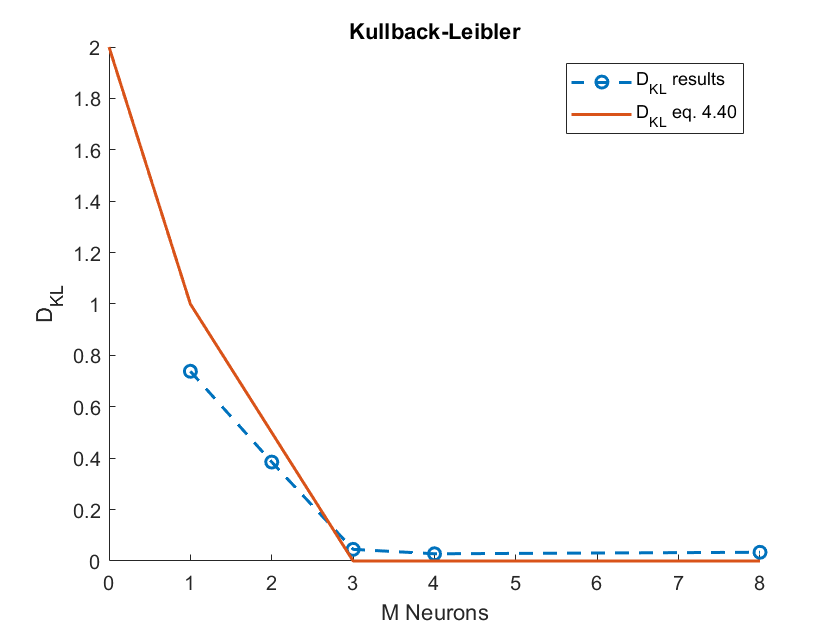

mHiddenNeurons = [1,2,3,4,8];

k = 200;
eta = 0.005;
nTrials = 500;
nMinibatches = 40;
nTrialsOuter = 300; 
nTrialsInner = 200;

data =    [-1,-1,-1;-1,1,1;1,-1,1;1,1,-1;1,1,1;-1,1,-1;-1,-1,1;1,-1,-1];
xorData = [-1,-1,-1;-1,1,1;1,-1,1;1,1,-1];

mSetsHiddenNeurons = length(mHiddenNeurons);
nPatterns = height(data);
dataProbs = zeros(nPatterns,mSetsHiddenNeurons);
kullback = zeros(1,mSetsHiddenNeurons);

% CD-k, algorithm 3 in the course book
for mNeurons = 1:mSetsHiddenNeurons
    
    % Averaging the Kullback-Leibler divergence to get a more precise estimate of the RBM's distribution
    nKullbackAvg = 1;
    for iKullbackAvg = 1:nKullbackAvg
        
        nHiddenNeurons = mHiddenNeurons(mNeurons);
        nVisibleNeurons = 3;

        w_ij = randn(nHiddenNeurons,nVisibleNeurons);
        theta_j = zeros(nVisibleNeurons,1);
        theta_i = zeros(nHiddenNeurons,1);
        
        h_i = zeros(nHiddenNeurons,1);
        b_i = zeros(nHiddenNeurons,1);
        v_j = zeros(nVisibleNeurons,1);
        b_j = zeros(nVisibleNeurons,1);
        
        probB_i = zeros(nHiddenNeurons,1);
        probB_j = zeros(nVisibleNeurons,1);
        
        % Training the Boltzmann machine for a number of trials
        for iTrial = 1:nTrials
            
            deltaWeight_ij = zeros(nHiddenNeurons,nVisibleNeurons);
            deltaTheta_j = zeros(nVisibleNeurons,1);
            deltaTheta_i = zeros(nHiddenNeurons,1);
                    
            % Training the Boltzmann machine over minibatches
            for iMiniBatch = 1:nMinibatches
                
                nXorPatterns = height(xorData);
                randPattern = randi(nXorPatterns);
                v_0 = xorData(randPattern,:)';
                
                % Updating hidden neurons
                for iNeuron = 1:nHiddenNeurons
                    b_i(iNeuron) = w_ij(iNeuron,:)*v_0 - theta_i(iNeuron);
                    probB_i(iNeuron) = 1/(1 + exp(-2*b_i(iNeuron)));
                    r = rand;
                    if r < probB_i(iNeuron)
                        h_i(iNeuron) = 1;
                    else
                        h_i(iNeuron) = -1;
                    end
                end
                
                % MCMC
                v_j = v_0;
                b_i0 = b_i;
                for t = 1:k
                    
                    % Updating visible neurons
                    for jNeuron = 1:nVisibleNeurons
                        b_j(jNeuron) = w_ij(:,jNeuron)'*h_i - theta_j(jNeuron);
                        probB_j(jNeuron) = 1/(1 + exp(-2*b_j(jNeuron)));
                        r = rand;
                        if r < probB_j(jNeuron)
                            v_j(jNeuron) = 1;
                        else
                            v_j(jNeuron) = -1;
                        end
                    end
                    
                    % Updating hidden neurons
                    for iNeuron = 1:nHiddenNeurons
                        b_i(iNeuron) = w_ij(iNeuron,:)*v_j - theta_i(iNeuron);
                        probB_i(iNeuron) = 1/(1 + exp(-2*b_i(iNeuron)));
                        r = rand;
                        if r < probB_i(iNeuron)
                            h_i(iNeuron) = 1;
                        else
                            h_i(iNeuron) = -1;
                        end
                    end
                end
                
                % Computing weight and threshold increments
                for iNeuron = 1:nHiddenNeurons
                    deltaWeight_ij(iNeuron,:) = deltaWeight_ij(iNeuron,:) + eta*(tanh(b_i0(iNeuron))*v_0 - tanh(b_i(iNeuron))*v_j)';
                end
                deltaTheta_j = deltaTheta_j - eta*(v_0 - v_j);
                deltaTheta_i = deltaTheta_i - eta*(tanh(b_i0) - tanh(b_i));
            end
            
            % Updating weights and thresholds 
            w_ij = w_ij + deltaWeight_ij;
            theta_j = theta_j + deltaTheta_j;
            theta_i = theta_i + deltaTheta_i;
        end
        
        % Computing the distribution of the trained Boltzmann machine
        counter = zeros(nPatterns,1);
        
        for iTrialOuter = 1:nTrialsOuter
            
            randPattern = randi(nPatterns);
            v_j = data(randPattern,:)';
            
            % Updating hidden neurons      
            for iNeuron = 1:nHiddenNeurons
                b_i(iNeuron) = w_ij(iNeuron,:)*v_j - theta_i(iNeuron);
                probB_i(iNeuron) = 1/(1 + exp(-2*b_i(iNeuron)));
                r = rand;
                if r < probB_i(iNeuron)
                    h_i(iNeuron) = 1;
                else
                    h_i(iNeuron) = -1;
                end
            end
            
            for iTrialInner = 1:nTrialsInner
                
                % Updating visible neurons
                for jNeuron = 1:nVisibleNeurons
                    b_j(jNeuron) = w_ij(:,jNeuron)'*h_i - theta_j(jNeuron);
                    probB_j(jNeuron) = 1/(1 + exp(-2*b_j(jNeuron)));
                    r = rand;
                    if r < probB_j(jNeuron)
                        v_j(jNeuron) = 1;
                    else
                        v_j(jNeuron) = -1;
                    end
                end
                
                % Updating hidden neurons
                for iNeuron = 1:nHiddenNeurons
                    b_i(iNeuron) = w_ij(iNeuron,:)*v_j - theta_i(iNeuron);
                    probB_i(iNeuron) = 1/(1 + exp(-2*b_i(iNeuron)));
                    r = rand;
                    if r < probB_i(iNeuron)
                        h_i(iNeuron) = 1;
                    else
                        h_i(iNeuron) = -1;
                    end
                end
                
                for muPattern = 1:nPatterns
                    target = data(muPattern,:)';
                    if isequal(v_j,target)
                        counter(muPattern) = counter(muPattern) + 1;
                        break
                    end
                end
            end
        end
        
        % Avergaing the distribution due to inner and outer trial loops
        for muPattern = 1:nPatterns
            dataProbs(muPattern,mNeurons) = counter(muPattern)/(nTrialsOuter*nTrialsInner);
        end
        
        % Computing the Kullback-Leibler divergence with the numerical results of the distribution
        pB = dataProbs(:,mNeurons);
        logPb = zeros(nPatterns,1);
        
        pData = 1/nXorPatterns;
        logPdata = log(pData);
        
        kullbackTemp = 0;
        for muPattern = 1:4
            if pB(muPattern) == 0
                logPb(muPattern) = 0;
            else
                logPb(muPattern) = log(pB(muPattern));
            end
            if muPattern > nXorPatterns
                pData = 0;
                logPdata = 0;
            end
            kullback(mNeurons) = kullback(mNeurons) + pData*(logPdata - logPb(muPattern));
        end
    end
    % Avergaing the Kullback-Leibler divergence
    kullback(mNeurons) = kullback(mNeurons) / nKullbackAvg;
end

% Computing the Kullback-Leibler divergence theory
kullbackTheoryX = 0:1:8;
kullbackTheoryY = kullbackTheoryX;
kullbackTheoryY = nVisibleNeurons - floor(log2(kullbackTheoryY' + 1)) - (kullbackTheoryY' + 1) ./ 2.^floor(log2(kullbackTheoryY' + 1));
kullbackTheoryY(4:9) = 0;

% Plotting the Kullback-Leibler divergence theory and numerical results as a function of M hidden neurons
figure
hold on
plot(mHiddenNeurons,kullback,"--o","Linewidth",1.5)
plot(kullbackTheoryX,kullbackTheoryY,"-","Linewidth",1.5)
title("Kullback-Leibler")
xlabel("M Neurons")
ylabel("D_{KL}")
legend("D_{KL} results","D_{KL} eq. 4.40")
hold off


dataProbs

dataProbs =     0.1297    0.1033    0.1975    0.1952    0.2681
    0.1038    0.1231    0.2719    0.2586    0.2994
    0.0800    0.2920    0.2925    0.3136    0.2388
    0.1892    0.2254    0.2074    0.2205    0.1778
    0.0916    0.0075    0.0044    0.0024    0.0054
    0.1688    0.1365    0.0072    0.0030    0.0040
    0.0905    0.1041    0.0102    0.0037    0.0036
    0.1464    0.0081    0.0089    0.0029    0.0028
